clc; clear; close all;

% Definir la función
f = @(x) 2*x.*cos(2*x) - (x + 1).^2;

% Intervalo inicial
a = -3;
b = -2;

% Número de iteraciones
num_iter = 5;

% Inicialización de la tabla
fprintf('Iteración |     a      |     b      |    f(a)     |    f(b)     |    x_i      |   f(x_i)    |   Error Relativo (%%) \n');

Iteración |     a      |     b      |    f(a)     |    f(b)     |    x_i      |   f(x_i)    |   Error Relativo (%) 


fprintf('--------------------------------------------------------------------------------------------------------\n');

--------------------------------------------------------------------------------------------------------



% Inicializar error relativo
error_relativo = NaN;

for i = 1:num_iter
    % Calcular x_i usando la fórmula de falsa posición
    x_i = b - (f(b) * (a - b)) / (f(a) - f(b));
    
    % Evaluar f(x_i)
    f_xi = f(x_i);
    
    % Calcular error relativo si no es la primera iteración
    if i > 1
        error_relativo = abs((x_i - x_ant) / x_i) * 100;
    end
    
    % Imprimir resultados en la tabla
    fprintf('%5d    | %9.4f | %9.4f | %10.4f | %10.4f | %10.4f | %10.4f | %10.4f \n', ...
        i, a, b, f(a), f(b), x_i, f_xi, error_relativo);
    
    % Actualizar los valores del intervalo
    if f_xi * f(a) < 0
        b = x_i;
    else
        a = x_i;
    end
    
    % Guardar el valor de x_i para la siguiente iteración
    x_ant = x_i;
end

    1    |   -3.0000 |   -2.0000 |    -9.7610 |     1.6146 |    -2.1419 |     0.4761 |        NaN 
    2    |   -3.0000 |   -2.1419 |    -9.7610 |     0.4761 |    -2.1818 |     0.0943 |     1.8289 
    3    |   -3.0000 |   -2.1818 |    -9.7610 |     0.0943 |    -2.1897 |     0.0165 |     0.3575 
    4    |   -3.0000 |   -2.1897 |    -9.7610 |     0.0165 |    -2.1910 |     0.0028 |     0.0623 
    5    |   -3.0000 |   -2.1910 |    -9.7610 |     0.0028 |    -2.1913 |     0.0005 |     0.0106 


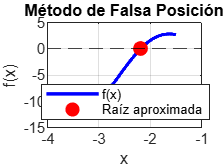


% Gráfica de la función
x = linspace(-3.5, -1.5, 1000);
y = f(x);

figure;
plot(x, y, 'b', 'LineWidth', 2); hold on;
plot(x_i, f(x_i), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % Punto de la raíz
yline(0, '--k'); % Línea horizontal en y = 0
xlabel('x');
ylabel('f(x)');
title('Método de Falsa Posición');
legend('f(x)', 'Raíz aproximada', 'Location', 'best');
grid on;